**General parameters and conversion gains**

% conversion gains
rpm2rads = 2*pi/60; 
rads2rpm = 60/2/pi; 
rpm2degs = 360/60;  
degs2rpm = 60/360;  
deg2rad = pi/180;   
rad2deg = 180/pi;   
ozin2Nm = 0.706e-2;	 

**DC motor nominal parameters**

% brushed DC−motor Faulhaber 2338S006S
mot.R = 2.6;                
mot.L = 180e-6;             
mot.Kt = 1.088 * ozin2Nm;   
mot.Ke = 0.804e-3 * rads2rpm; 
mot.J = 5.523e-5 * ozin2Nm; 
mot.B = 0.0;                
mot.eta  = 0.69;                
mot.PN   = 3.23/mot.eta;        
mot.UN   = 6;               
mot.IN   = mot.PN/mot.UN;   
mot.tauN = mot.Kt*mot.IN;   
mot.taus = 2.42 * ozin2Nm;  
mot.w0 = 7200 * rpm2rads;   

**Gearbox nominal parameters**

% planetary gearbox Micromotor SA 23/1
gbox.N1 = 14; 
gbox.eta1 = 0.80;  

% external transmission gears
gbox.N2 = 1; 
gbox.J72 = 1.4e-6; 
gbox.eta2 = 1;

% overall gearbox data
gbox.N   = gbox.N1*gbox.N2;         
gbox.eta = gbox.eta1*gbox.eta2;     
gbox.J = 3*gbox.J72;

**Mechanical load nominal parameters**

% inertia disc params
mld.JD = 3e-5; 
mld.BD = 0.0; 

% overall mech load params
mld.J = mld.JD + gbox.J;        
mld.B = 2.5e-4; 
mld.tausf = 1.0e-2; 

**Voltage driver nominal parameters**

% op−amp circuit params
drv.R1 = 7.5e3; 
drv.R2 = 1.6e3; 
drv.R3 = 1.2e3; 
drv.R4 = 0.5e3; 
drv.C1 = 100e-9; 
drv.outmax = 12; 


% voltage driver dc−gain
drv.dcgain = drv.R2/(drv.R1+drv.R2) * (1 + drv.R3/drv.R4);

% voltage driver time constant
drv.Tc = drv.C1 * drv.R1*drv.R2/(drv.R1+drv.R2);

**Sensors data**

% Shunt resistor
sens.curr.Rs = 0.5;

% Hewlett−Packard HEDS−5540#A06 optical encoder
sens.enc.ppr = 500*4; 
sens.enc.pulse2deg = 360/sens.enc.ppr;
sens.enc.pulse2rad = 2*pi/sens.enc.ppr;
sens.enc.deg2pulse = sens.enc.ppr/360;
sens.enc.rad2pulse = sens.enc.ppr/2/pi; 

% potentiometer 1 (Spectrol 138−0−0−103) − installed on motor box
sens.pot1.range.R = 10e3; 
sens.pot1.range.V = 5; 
sens.pot1.range.th_deg = 345; 
sens.pot1.range.th = sens.pot1.range.th_deg * deg2rad; 
sens.pot1.deg2V = sens.pot1.range.V / sens.pot1.range.th_deg;
sens.pot1.rad2V = sens.pot1.range.V / sens.pot1.range.th;
sens.pot1.V2deg = 1/sens.pot1.deg2V;
sens.pot1.V2rad = 1/sens.pot1.rad2V; 


**Data acquisition board**

% (daq) data NI PCI−6221 DAC data
daq.dac.bits = 16; 
daq.dac.fs = 10; % full scale
daq.dac.q = 2*daq.dac.fs/(2^daq.dac.bits-1); % quantization

% NI PCI−6221 ADC data
daq.adc.bits = 16; % resolution (bits)
daq.adc.fs = 10; % full scale (as set in SLDRT Analog Input block)
daq.adc.q = 2*daq.adc.fs/(2^daq.adc.bits-1); % quantization

**Varie**

extra.Jl = mot.J + 3*gbox.J72;
N = 14;

% Filtri
filt.omega = 2*pi*50;
filt.Tc = 1/filt.omega;
filt.delta = 1/sqrt(2);

**Plot della simulazione** **[****NO CONTROL****]**

% figure
% subplot(4,1,1)
% plot(out.thl)
% hold on 
% plot(out.thl_meas)
% ylabel('\theta_{l} [deg]')
% axis([0 3 0 4000])
% 
% subplot(4,1,2)
% plot(out.wl)
% hold on 
% plot(out.wl_meas)
% ylabel('\omega_{l} [deg]')
% axis([0 3 -400 400])
% 
% subplot(4,1,3)
% plot(out.udrv)
% ylabel('u [V]')
% axis([0 3 -10 10])
% 
% subplot(4,1,4)
% plot(out.ia)
% ylabel('i_{a} [A]')
% axis([0 3 -2 2])


**Plot della simulazione** **[****WITH** **CONTROL****]**

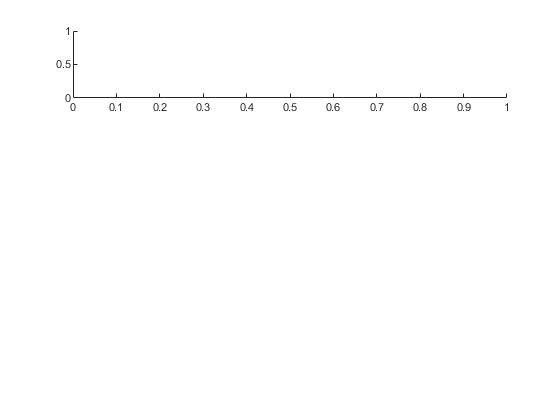

figure
subplot(4,1,1)

plot(out.wl_meas)

Unable to resolve the name out.wl_meas.

hold on 
plot(out.ref)
ylabel('\omega_{l} [deg]')
axis([0 20 -450 450])

subplot(4,1,2)
plot(out.e)
ylabel('e [rpm]')
axis([0 20 -100 100])


subplot(4,1,3)
plot(out.udrv)
ylabel('u [V]')
axis([0 20 -10 10])

subplot(4,1,4)
plot(out.ia)
ylabel('i_{a} [A]')
axis([0 20 -2 2])